## Tutorial 3.1

Se creó la función** lagd.m**

La respuesta de impulso en tiempo discreto del sistema se genera para el valor numérico experimento. Se utiliza la función MATLAB dimpulse.m para obtener los datos de respuesta de impulso de un modelo de función de transferencia.

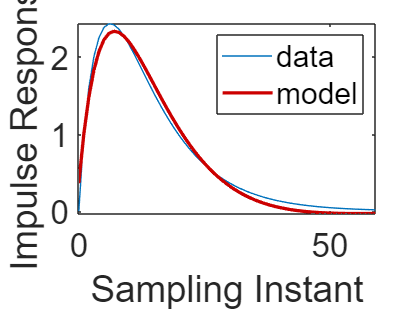

%Se creó la función lagd.m
% lagdmodel.m
clear all; close all; clc;

numd=[1 -0.1];
dend=conv([1 -0.8],[1 -0.9]);
N_sim=60;
k=0:(N_sim); % Cambio aqui
H=dimpulse(numd,dend,k);

% Generar funciones de Laguerre para a y N
a=0.9;  % Variar a tiene efecto
N=3;    % Variar N no tiene efecto
[A1,L0]=lagd(a,N);
L(:,1)=L0;
for kk=2:N_sim
    L(:,kk)=A1*L(:,kk-1);
end
% * y .* son distintas
% * = Multiplicación vectorial
% .* = Multiplicación elemento a elemento

% Calculo de los coeficientes de Laguerre
c1=L(1,:)*H;
c2=L(2,:)*H;
c3=L(3,:)*H;
H_model=c1*L(1,:)+c2*L(2,:)+c3*L(3,:);

figure(1)
plot(k(1:60),H)
hold on
plot(k(1:60),H_model,'LineWidth',2,'Color',[.8 0 0])
set(gca,'FontSize',20,'FontName','helvetica');
legend('data','model')
xlabel('Sampling Instant')
ylabel('Impulse Response')

## Tutorial 3.2

Escriba una función de MATLAB dmpc.m para generar las matrices de datos en el diseño de un sistema de control predictivo de modelo de tiempo discreto donde la función de costo se expresa como

con funciones de Laguerre para un sistema multientrada con matriz de peso $Q$ sobre las variables de estado y $R$ sobre las variables de entrada.

Se creó la función **dmpc.m**, la cual retorna:

## Tutorial 3.3

% testexa.m

% 5 Entradas y 4 Salidas

%First row
n11=0.34;
d11=[0.85 1];
n12=0.21;
d12=[0.42 1];
n13=0.50*[0.50 1];
d13=[12 0.4 1];
n14=0;
d14=1;
n15=6.46*[0.9 1];
d15=[0.07 0.3 1];
%second row
n21=-0.41;
d21=[2.41 1];
n22=0.66;
d22=[1.51 1];
n23=-0.3;
d23=[1.45 1];
n24=0;
d24=1;
n25=-3.72;
d25=[0.8 1];
%third row
n31=0.3;
d31=[2.54 1];
n32=0.49;
d32=[1.54 1];
n33=-0.71;
d33=[1.35 1];
n34=-0.20;
d34=[2.71 1];
n35=-4.71;
d35=[0.008 0.41 1];
%fourth row
n41=0;
d41=1;
n42=0;
d42=1;
n43=0;
d43=1;
n44=0;
d44=1;
n45=1.02;
d45=[0.07 0.31 1];

h=1; %sampling interval
Gs=tf({n11 n12 n13 n14 n15;n21 n22 n23 n24 n25;
n31 n32 n33 n34 n35;n41 n42 n43 n44 n45},{d11 d12 d13 d14 d15;d21 d22 d23 d24 d25;
d31 d32 d33 d34 d35;d41 d42 d43 d44 d45});
Gsmin=ss(Gs,'min');
[Ac,Bc,Cc,Dc]=ssdata(Gsmin);
[Ap,Bp,Cp,Dp]=c2dm(Ac,Bc,Cc,Dc,h,'zoh');
[m1,n1]=size(Cp);
[n1,n_in]=size(Bp);

% Parámetros de Laguerre para cada entrada
a1=0.5;
a2=0.5;
a3=0.5;
a4=0.5;
a5=0.5;
N1=10;
N2=10;
N3=10;
N4=10;
N5=10;
a=[a1 a2 a3 a4 a5];
N=[N1 N2 N3 N4 N5];
Np=100;

%%%%%%%%%%%%%%%%
%Augment state equations
%%%%%%%%%%%%%%%%
A_e=eye(n1+m1,n1+m1);
A_e(1:n1,1:n1)=Ap;
A_e(n1+1:n1+m1,1:n1)=Cp*Ap;
B_e=zeros(n1+m1,n_in);
B_e(1:n1,:)=Bp;
B_e(n1+1:n1+m1,:)=Cp*Bp;
C_e=zeros(m1,n1+m1);
C_e(:,n1+1:n1+m1)=eye(m1,m1);
Q=C_e'*C_e;
R=0.1*eye(n_in,n_in);

[Omega,Psi]=dmpc(A_e,B_e,a,N,Np,Q,R);
L_m=zeros(n_in,sum(N));
[A1,L0]=lagd(a(1),N(1));
L_m(1,1:N(1))=L0';
In_s=1;
for jj=2:n_in
    [Al,L0]=lagd(a(jj),N(jj));
    In_s=N(jj-1)+In_s;
    In_e=In_s+N(jj)-1;
    L_m(jj,In_s:In_e)=L0';
end
K=L_m*(Omega\Psi);
Acl=A_e-B_e*K;

El programa anterior produce el control predictivo del modelo de tiempo discreto usando funciones de Laguerre. La ganancia de control de retroalimentación de estado es $K$ y la matriz del sistema de bucle cerrado es $Acl$.

**dlqr():** Regulador lineal cuadrático (LQ) de feedback de estados para un sistema de espacio de estados de tiempo discreto.

[X,Y,Z]=dlqr(A_e,B_e,Q,R);
% Z = e = eig(A-B*K)
figure(2)
plot(Z,'ro')        % Polos del DLQR

hold on
plot(eig(Acl),'b*') % Polos del MPC

xlabel('Real')
ylabel('Imaginario')
title('Funciones de Laguerre con a')
legend('dlqr','dmpc')

## Tutorial 3.4

Este tutorial es para producir una simulación de bucle cerrado multivariable para sistemas de control predictivo **sin restricciones**. 

El desempeño de un sistema sin restricciones debe verificarse antes de introducir las restricciones.

No se utiliza ningún observador en el primer programa. Se incluye un observador en el segundo programa. 

Se creó la función** simuuc.m**

## **Turtorial 3.5**

Necesitamos probar el programa de simulación MPC **simuuc.m** antes de su aplicación. El ejemplo de prueba se deriva del sistema MPC diseñado en el Tutorial 3.3.Este tutorial continúa desde el programa testexa.m de MATLAB. A continuación,simularemos la respuesta del sistema en lazo cerrado usando la función simuus.m. Primero se especifican las condiciones iniciales para la simulación y se llama a la función para producir las respuestas de lazo cerrado. Lzerot es la matriz utilizada para reconstruir el $\Delta u(k_i)$ con el vector de parámetros $\eta$ (ver (3.46)), el cual está incluido en el programa **Mdu.m** (ver Tutorial 3.7).

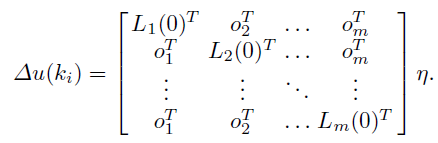

%testexa1.m

y=zeros(m1,1);
u=zeros(n_in,1);
xm=zeros(n1,1);
N_sim=100;

r1=ones(1,N_sim+10);
r2=zeros(1,N_sim+10);
r3=zeros(1,N_sim+10);
r4=zeros(1,N_sim+10);
sp=[r1;r2;r3;r4];

[M,Lzerot]=Mdu(a,N,n_in,1);

Xf=[xm;(y-sp(:,1))]

Xf =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


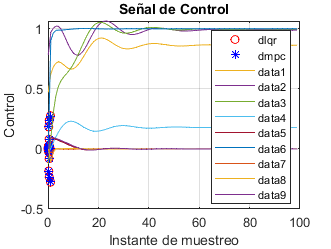


% Xf = 22x1
% xm = 18x1
% y = 4x1
% sp = 4x110


[u1,y1,deltau1,k]=simuuc(xm,u,y,sp,Ap,Bp,Cp,N_sim,Omega,Psi,Lzerot);

figure(3)
plot(k,u1)
grid on
xlabel('Instante de muestreo')
ylabel('Salida')
title('Respuesta de salida')

figure(4)
plot(k,y1)
grid on
xlabel('Instante de muestreo')
ylabel('Control')
title('Señal de Control')

## Tutorial 3.6

Este tutorial produce una simulación de bucle cerrado para sistemas de control predictivo con un observador en el bucle. El programa es muy similar al presentado en el Tutorial 3.4. Sin embargo, la variable de retroalimentación se basa en la variable de estado estimada $x_{hat}
$.

Se creó la función **simuob.m**

**sp** es una señal que tiene un número de filas igual al número de salidas y un número de columnas mayor que el número de simulación.

**QPhild: **El programa encuentra la solución óptima global y comprueba si se cumplen todas las restricciones. Si es así, el programa devuelve la solución óptima $\eta$. Si no, el programa comienza a calcular la variable dual $\lambda$.

% eta=QPhild(Omega,Psi*Xf,M,gamma);

## Tutorial 3.7

Escriba un programa de MATLAB para generar la matriz $M$utilizado en la restricción de la diferencia de la señal de control es decir, $\Delta u(k)$.

$M $es la matriz de datos para imponer restricciones en las primeras $N_c$ muestras en $\Delta u(k_i)$. La matriz de bloques Lzerot se utiliza para construir la señal de control.

Se creó la función **Mdu.m**

% a = 0;
% N = 3;
% n_in = 1;
% Nc = 3;

a = [0.2 0.3];
N = [3 3];
n_in = 2;
Nc = 5;

[M,Lzerot]=Mdu(a,N,n_in,Nc)

M =     0.9798   -0.1960    0.0392         0         0         0
         0         0         0    0.9539   -0.2862    0.0859
    0.1960    0.9014   -0.3684         0         0         0
         0         0         0    0.2862    0.7822   -0.4951
    0.0392    0.3684    0.7541         0         0         0
         0         0         0    0.0859    0.4951    0.4852
    0.0078    0.1113    0.4970         0         0         0
         0         0         0    0.0258    0.2267    0.5726
    0.0016    0.0298    0.2047         0         0         0
         0         0         0    0.0077    0.0914    0.3710


Lzerot =     0.9798   -0.1960    0.0392         0         0         0
         0         0         0    0.9539   -0.2862    0.0859


clear all; close all; clc;

## **Ejemplo 3.6** - Restricciones en la Tasa de Cambio

El objetivo es encontrar $\eta$ y $\Delta u(k_i+m)$ sujetas a las restricciones:

zita = 0.1;
Om = 3;
h = 0.1;
Np = 46;

a = 0.7;
N = 8;

Gs=tf(1, [1 2*zita*Om Om^2]);
Gsmin=ss(Gs,'min');
[Ac,Bc,Cc,Dc]=ssdata(Gsmin);
[Ap,Bp,Cp,Dp]=c2dm(Ac,Bc,Cc,Dc,h,'zoh');
[m1,n1]=size(Cp);
[n1,n_in]=size(Bp);
A_e=eye(n1+m1,n1+m1);
A_e(1:n1,1:n1)=Ap;
A_e(n1+1:n1+m1,1:n1)=Cp*Ap;
B_e=zeros(n1+m1,n_in);
B_e(1:n1,:)=Bp;
B_e(n1+1:n1+m1,:)=Cp*Bp;
C_e=zeros(m1,n1+m1);
C_e(:,n1+1:n1+m1)=eye(m1,m1);
Q=C_e'*C_e;
R=0.3*eye(n_in,n_in);

A = A_e;
B = B_e;

[Omega,Psi]=dmpc(A,B,a,N,Np,Q,R);

% Restricciones
Deltau_min=-1;
Deltau_max=0.25;

Nc=15;
X0=[0.1;0.2;0.3];
[M0,Lzerot]=Mdu(a,N,1,Nc);
M=[M0;-M0];
gamma=[Deltau_max*ones(Nc,1);
      -Deltau_min*ones(Nc,1)];
eta=QPhild(Omega,Psi*X0,M,gamma);

## Tutorial 3.8

Escriba un programa de MATLAB para generar la matriz $M$utilizado en la restricción de la señal de control es decir, $u(k)$.

Se creó la función **Mu.m**

a = 0;
N = 3;
n_in = 1;
Nc = 3;

% a = [0.2 0.3];
% N = [3 3];
% n_in = 2;
% Nc = 5;

M=Mu(a,N,n_in,Nc)

M =      1     0     0
     1     1     0
     1     1     1


## **Ejemplo 3.7** - Restricciones en la Amplitud 

El objetivo es encontrar $\eta$ y $\Delta u(k_i+m)$ sujetas a las restricciones:

[Omega,Psi]=dmpc(A,B,a,N,Np,Q,R);
X0=[0.1;0.2;0.3];
up=6;

% Restricciones
u_min=1.8;
u_max=4;

% Esto lo agregamos nosotros, para corregir el error en QPhild
Nc=Np;

M0=Mu(a,N,1,Np);
M=[M0;-M0];
gamma=[(u_max-up)*ones(Nc,1);(-u_min+up)*ones(Nc,1)];
eta=QPhild(Omega,Psi*X0,M,gamma);
%% No funcionada por problemas en M o gamma

## **Ejemplo 3.8**

Este ejemplo muestra que cuando ambas restricciones se juntan, no se pueden cumplir en la misma muestra inicial. Como resultado, la solución óptima se ve comprometida.

                

[Omega,Psi]=dmpc(A,B,a,N,Np,Q,R);

% Condiciones
X0=[0.1;0.2;0.3];
up=6;

% Restricciones
Deltau_min=-1;
Deltau_max=0.25;
u_min=1.8;
u_max=4;

Nc=Np;
[M1,Lzerot]=Mdu(a,N,1,Nc);
M0=Mu(a,N,1,Nc);
M=[M0;-M0;M1;-M1];
gamma=[(u_max-up)*ones(Nc,1);(-u_min+up)*ones(Nc,1);
Deltau_max*ones(Nc,1); -Deltau_min*ones(Nc,1)];
eta=QPhild(Omega,Psi*X0,M,gamma);

% A_e = 3x3
% B_e = 3x1
% Psi = 8x3
% X0 = 3x1

Gráficas

% k=0:(Nc-1);
% 
% figure(5)
% plot(k,y1,'b')
% ylabel('y')
% xlabel('Sampling Instant')
% subplot(212)
% plot(k,u1,'b')
% ylabel('u')
% xlabel('Sampling Instant')
% 
% figure(6)
% plot(k,deltau1,'g')
% ylabel('Delta u')
% xlabel('Sampling Instant')